# INVASIVE MODAL CONTROL

a_model_setup

% Time and sampling
T_total = 2;
Ts = 1/1000;
t_vec = 0:Ts:T_total;
t_num = length(t_vec);

% Initial state: [eta1, eta2, eta_dot1, eta_dot2, I, psi]
x0 = zeros(5,1);

% Store history
t_all = t_vec';
x_all = zeros(t_num, 5);
v_all = zeros(t_num, 1);

% Control gains
model.k1 = 10000/1.5;
model.k2 = 0;
model.Ts = Ts;

% Desired trajectory
A_target = 0.002;                 % target amplitude (m)
omega = model.omega;             % target frequency (rad/s)
model.eta_star = @(t) A_target.*sin(omega.*t);


% Initialize control state
psi_0 = 0.1;
u_k = 0;

for k = 1:length(t_vec)-1
    tk = t_all(k);
    tkp1 = t_all(k+1);
    tspan = [tk, tkp1];
    
    % control force:
    eta_e1 = model.eta_star(tk) - x_all(k, 1);
    control_volt = model.k1*eta_e1;
    v_all(k) = control_volt;
    model.u_fun = @(t) control_volt;

    % simulate between samples
    [t_seg, x_seg] = ode45(@(t,x) f_beam_shaker_model(t, x, model), tspan, x0);

    x0 = x_seg(end,:)';
    x_all(k+1, :) = x0;
end

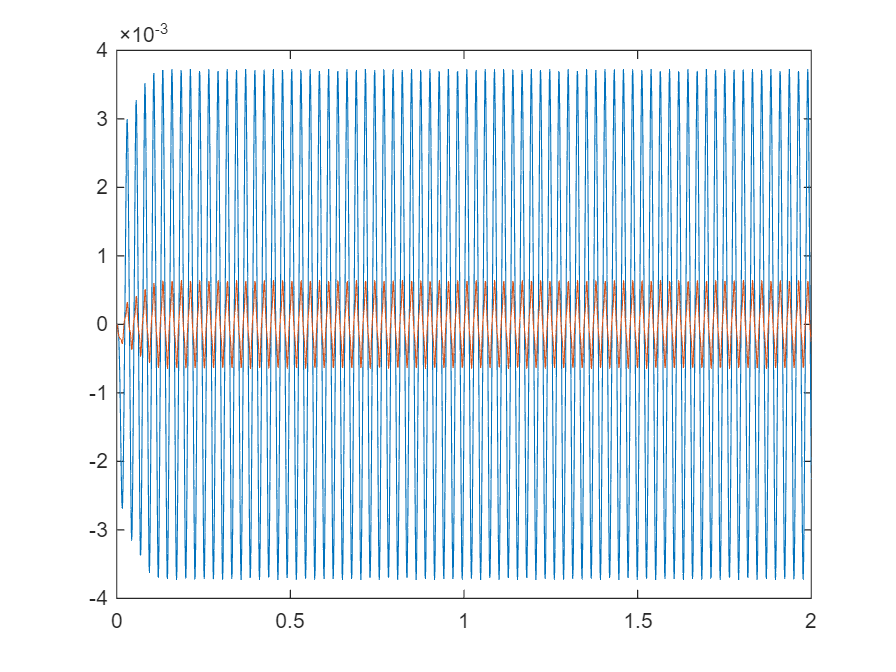

figure;
plot(t_all, x_all(:, 1:2))
hold on;

% plot(t_all, v_all./10000)

omega/(2*pi)*0.5

ans = 18.8400